Tutorial 4.3 Computational Neuroscience Jacob Smith

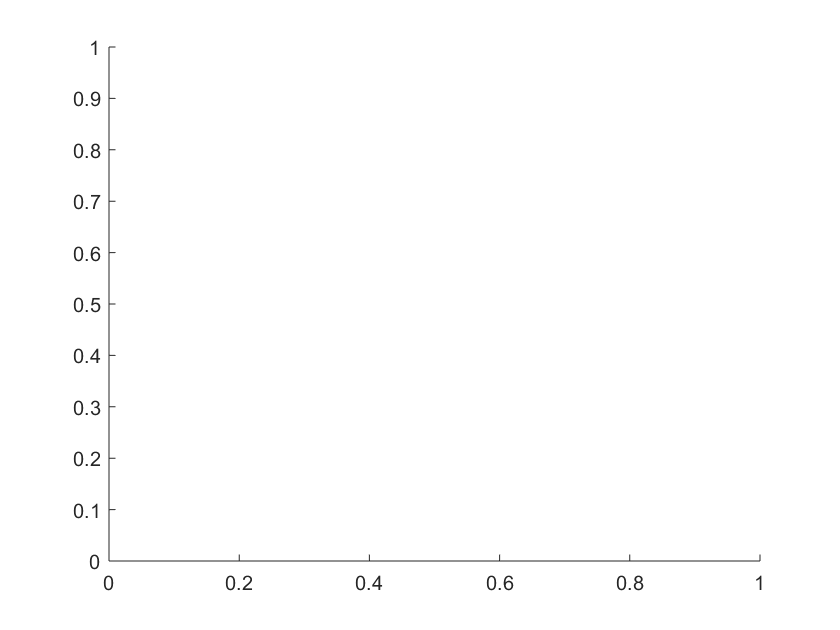

Error using plot
Vectors must be the same length.

Error in plotFigureTable (line 9)
    plot(independent,row);

clear;
%4.3.2
V_M=-.085:.1:.05;

M_CA=0:1e-4:2e-3;
[ ~,~,~,~, alpha_kahp, beta_kahp ] =PR_dend_gating(V_M,M_CA);
matrix=loadTable(alpha_kahp, beta_kahp );
names=[ "alpha_kahp", "beta_kahp"];
plotFigureTable(matrix,V_M,names,"Time (s)","V_M (V)","Tutorial 4.2.2a");

%[ alpha_mca, beta_mca, alpha_kca, beta_kca, alpha_kahp, beta_kahp ] =PR_soma_gating(V_M);


function A=loadTable(alpha_kahp, beta_kahp)
%Organzies the gating variable into a matrix so they can be used with a central graphing function 
A=zeros(2,length(alpha_kahp));
A(1,:)=alpha_kahp;
A(2,:)=beta_kahp;
return;
end